# Average Power - Habituated Vs. Unhabituated in KO and Control

## Summary

The purpose of this script is to find the average power at each frequency for each mouse in the habituated and unhabituated states

Steps:

- Make each trial 1,800,000 samples (= 1,800,000 ms = 30 mins = length of shortest habituated trial)

- Visually analyze data with basic spectrogram and remove artifacts

- Vertically concatenate habituated and unhabituated trials for each mouse

- Use function mtspectrumsegc to take average power over window of 10 seconds and average all together 

- Compare

##  Load Datasets into Grouped Conditions

% Load each unhabituated trial for each
controls_unhabituated_unstandardized = {CT2, CT4}

controls_unhabituated_unstandardized = 1×2 cell array
    {3726858×2 single}    {3675772×2 single}


knockouts_unhabituated_unstandardized = {KO2, KO4}

knockouts_unhabituated_unstandardized = 1×2 cell array
    {3689071×2 single}    {3770358×2 single}



% Load each habituated trial for each
controls_habituated_unstandardized={CT1, CT3, CT8}

controls_habituated_unstandardized = 1×3 cell array
    {1893260×2 single}    {3716176×2 single}    {3653016×2 single}


knockouts_habituated_unstandardized= {KO1, KO3, KO8}

knockouts_habituated_unstandardized = 1×3 cell array
    {1890190×2 single}    {3517539×2 single}    {3861380×2 single}


## Standardize Length of Each Dataset

% Standardize the lengths of each array 
desired_length = 1000000

desired_length = 1000000


scontrols_unhab_w60 = standardize_length(controls_unhabituated_unstandardized, desired_length)

cell_array = 1×2 cell array
    {1000000×2 single}    {3675772×2 single}


cell_array = 1×2 cell array
    {1000000×2 single}    {1000000×2 single}


result = 1×2 cell array
    {1000000×2 single}    {1000000×2 single}


scontrols_unhab_w60 = 1×2 cell array
    {1000000×2 single}    {1000000×2 single}


sknockouts_unhab_w60 = standardize_length(knockouts_unhabituated_unstandardized, desired_length)

cell_array = 1×2 cell array
    {1000000×2 single}    {3770358×2 single}


cell_array = 1×2 cell array
    {1000000×2 single}    {1000000×2 single}


result = 1×2 cell array
    {1000000×2 single}    {1000000×2 single}


sknockouts_unhab_w60 = 1×2 cell array
    {1000000×2 single}    {1000000×2 single}



scontrols_hab_w60 = standardize_length(controls_habituated_unstandardized, desired_length) 

cell_array = 1×3 cell array
    {1000000×2 single}    {3716176×2 single}    {3653016×2 single}


cell_array = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {3653016×2 single}


cell_array = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {1000000×2 single}


result = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {1000000×2 single}


scontrols_hab_w60 = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {1000000×2 single}


sknockouts_hab_w60 = standardize_length(knockouts_habituated_unstandardized, desired_length)

cell_array = 1×3 cell array
    {1000000×2 single}    {3517539×2 single}    {3861380×2 single}


cell_array = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {3861380×2 single}


cell_array = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {1000000×2 single}


result = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {1000000×2 single}


sknockouts_hab_w60 = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {1000000×2 single}


## Set Parameters for Chronux Spectrogram

% Setting parameters
params.Fs = 1000; %Sampling frequency of input data (1000 = 1000 hz = 1 sample per millisecond)
params.fpass = [0 100]; % Which frequencies to look at [lowest_wanted highest_wanted]
params.pad = 0; % will add 0's to fit into a power of 2 for better calculation (0 is default and adds 0's to the next power of 2)
TW = 5; % the time-bandwidth product 
K = 9; % the number of tapers, K = 2*TW - 1 
params.tapers = [TW K]; 



## Filter out 60 Hz Signal from Each

% removing 60 Hz
scontrols_unhab = remove60(scontrols_unhab_w60, params.Fs)

cell_array = 1×2 cell array
    {1000000×2 single}    {1000000×2 single}


cell_array = 1×2 cell array
    {1000000×2 single}    {1000000×2 single}


result = 1×2 cell array
    {1000000×2 single}    {1000000×2 single}


scontrols_unhab = 1×2 cell array
    {1000000×2 single}    {1000000×2 single}


sknockouts_unhab =  remove60(sknockouts_unhab_w60, params.Fs)

cell_array = 1×2 cell array
    {1000000×2 single}    {1000000×2 single}


cell_array = 1×2 cell array
    {1000000×2 single}    {1000000×2 single}


result = 1×2 cell array
    {1000000×2 single}    {1000000×2 single}


sknockouts_unhab = 1×2 cell array
    {1000000×2 single}    {1000000×2 single}



scontrols_hab = remove60(scontrols_hab_w60, params.Fs)

cell_array = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {1000000×2 single}


cell_array = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {1000000×2 single}


cell_array = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {1000000×2 single}


result = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {1000000×2 single}


scontrols_hab = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {1000000×2 single}


sknockouts_hab = remove60(sknockouts_hab_w60, params.Fs)

cell_array = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {1000000×2 single}


cell_array = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {1000000×2 single}


cell_array = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {1000000×2 single}


result = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {1000000×2 single}


sknockouts_hab = 1×3 cell array
    {1000000×2 single}    {1000000×2 single}    {1000000×2 single}


## Print out Spectrum for each to Look for Artifacts

%Test printing one spectrum (maybe write function to interatively print spectrums)

scontrols_unhab{1}

ans = 1000000×2 single matrix
   -0.5502    0.9033
   -0.5538    0.8585
   -0.5545    0.8965
   -0.5555    0.8463
   -0.5545    0.8610
   -0.5568    0.9026
   -0.5607    0.9011
   -0.5565    0.9909
   -0.5588    1.0482
   -0.5624    1.0340


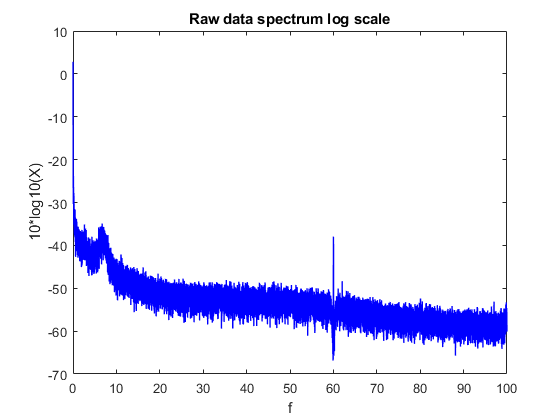


[S,f] = mtspectrumc(scontrols_unhab{1}(:,2),params);

figure; plot_vector(S,f); title('Raw data spectrum log scale');

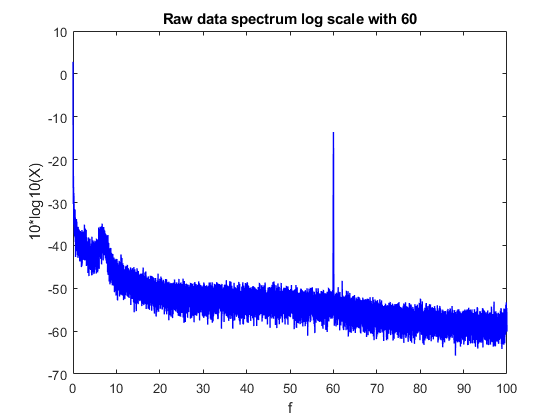




[S,f] = mtspectrumc(scontrols_unhab_w60{1}(:,2),params);


figure; plot_vector(S,f); title('Raw data spectrum log scale with 60');

## Print Spectrogram for Each to Look for Artifacts

% compute spectogram


movingwin = [5 .5]; % Larger window sizes = more frequency bands. Larger step sizes, more blurring > used to use [10 .5], better would be [20 1]


% Set Data
data = scontrols_unhab_w60{1}(:,2)

data = 1000000×1 single column vector
    0.9033
    0.8619
    0.9024
    0.8537
    0.8685
    0.9089
    0.9053
    0.9922
    1.0464
    1.0293


datano60 = scontrols_unhab{1}(:,2)

datano60 = 1000000×1 single column vector
    0.9033
    0.8585
    0.8965
    0.8463
    0.8610
    0.9026
    0.9011
    0.9909
    1.0482
    1.0340


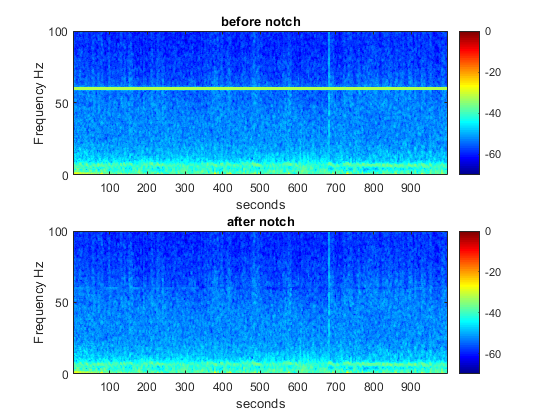


% Compute Spectrograms
[S1,t,f] = mtspecgramc(data,movingwin,params);
[S2,t,f] = mtspecgramc(datano60,movingwin,params);
   
%Plot Spectrograms

figure;
subplot(2,1,1);plot_matrix(S1,t,f);
xlabel('seconds'); ylabel('Frequency Hz'); title('before notch');ylim([0 100]); caxis([-70 0]);
subplot(2,1,2);plot_matrix(S2,t,f);
xlabel('seconds'); ylabel('Frequency Hz'); colorbar; colormap jet; title('after notch');ylim([0 100]); caxis([-70 0]);

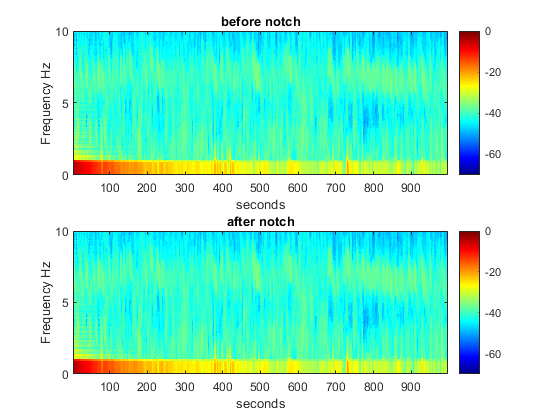


figure;
subplot(2,1,1);plot_matrix(S1,t,f);
xlabel('seconds'); ylabel('Frequency Hz'); title('before notch');ylim([0 10]); caxis([-70 0]);
subplot(2,1,2);plot_matrix(S2,t,f);
xlabel('seconds'); ylabel('Frequency Hz'); colorbar; colormap jet; title('after notch');ylim([0 10]); caxis([-70 0]);

## Vertically Concatenate Arrays from each Condition

KO_unhab_cat = vertcat_cell_array(sknockouts_unhab)

x = 1000000×2 single matrix
   -2.3264    0.0218
   -2.3278    0.0115
   -2.3255    0.0312
   -2.3261    0.0377
   -2.3281    0.0364
   -2.3278    0.0219
   -2.3264   -0.0195
   -2.3281   -0.0298
   -2.3268   -0.0610
   -2.3274   -0.0594


x = 2000000×2 single matrix
   -2.3264    0.0218
   -2.3278    0.0115
   -2.3255    0.0312
   -2.3261    0.0377
   -2.3281    0.0364
   -2.3278    0.0219
   -2.3264   -0.0195
   -2.3281   -0.0298
   -2.3268   -0.0610
   -2.3274   -0.0594


result = 2000000×2 single matrix
   -2.3264    0.0218
   -2.3278    0.0115
   -2.3255    0.0312
   -2.3261    0.0377
   -2.3281    0.0364
   -2.3278    0.0219
   -2.3264   -0.0195
   -2.3281   -0.0298
   -2.3268   -0.0610
   -2.3274   -0.0594


KO_unhab_cat = 2000000×2 single matrix
   -2.3264    0.0218
   -2.3278    0.0115
   -2.3255    0.0312
   -2.3261    0.0377
   -2.3281    0.0364
   -2.3278    0.0219
   -2.3264   -0.0195
   -2.3281   -0.0298
   -2.3268   -0.0610
   -2.3274   -0.0594


CTL_unhab_cat = vertcat_cell_array(scontrols_unhab)

x = 1000000×2 single matrix
   -0.5502    0.9033
   -0.5538    0.8585
   -0.5545    0.8965
   -0.5555    0.8463
   -0.5545    0.8610
   -0.5568    0.9026
   -0.5607    0.9011
   -0.5565    0.9909
   -0.5588    1.0482
   -0.5624    1.0340


x = 2000000×2 single matrix
   -0.5502    0.9033
   -0.5538    0.8585
   -0.5545    0.8965
   -0.5555    0.8463
   -0.5545    0.8610
   -0.5568    0.9026
   -0.5607    0.9011
   -0.5565    0.9909
   -0.5588    1.0482
   -0.5624    1.0340


result = 2000000×2 single matrix
   -0.5502    0.9033
   -0.5538    0.8585
   -0.5545    0.8965
   -0.5555    0.8463
   -0.5545    0.8610
   -0.5568    0.9026
   -0.5607    0.9011
   -0.5565    0.9909
   -0.5588    1.0482
   -0.5624    1.0340


CTL_unhab_cat = 2000000×2 single matrix
   -0.5502    0.9033
   -0.5538    0.8585
   -0.5545    0.8965
   -0.5555    0.8463
   -0.5545    0.8610
   -0.5568    0.9026
   -0.5607    0.9011
   -0.5565    0.9909
   -0.5588    1.0482
   -0.5624    1.0340



KO_hab_cat = vertcat_cell_array(sknockouts_hab)

x = 1000000×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0757
    0.0024   -0.0452
    0.0054   -0.0557
    0.0034   -0.0409
    0.0037    0.0106
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0679
    0.0027   -0.0696


x = 2000000×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0757
    0.0024   -0.0452
    0.0054   -0.0557
    0.0034   -0.0409
    0.0037    0.0106
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0679
    0.0027   -0.0696


x = 3000000×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0757
    0.0024   -0.0452
    0.0054   -0.0557
    0.0034   -0.0409
    0.0037    0.0106
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0679
    0.0027   -0.0696


result = 3000000×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0757
    0.0024   -0.0452
    0.0054   -0.0557
    0.0034   -0.0409
    0.0037    0.0106
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0679
    0.0027   -0.0696


KO_hab_cat = 3000000×2 single matrix
    0.0040   -0.0496
    0.0034   -0.0757
    0.0024   -0.0452
    0.0054   -0.0557
    0.0034   -0.0409
    0.0037    0.0106
    0.0044   -0.0802
    0.0050   -0.0506
    0.0031   -0.0679
    0.0027   -0.0696


CTL_hab_cat = vertcat_cell_array(scontrols_hab)

x = 1000000×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0589
    0.0165   -0.0739
    0.0149   -0.0638
    0.0156   -0.0766
    0.0123    0.0013
    0.0146   -0.0047
    0.0152   -0.0100
    0.0136   -0.0229
    0.0156   -0.0399


x = 2000000×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0589
    0.0165   -0.0739
    0.0149   -0.0638
    0.0156   -0.0766
    0.0123    0.0013
    0.0146   -0.0047
    0.0152   -0.0100
    0.0136   -0.0229
    0.0156   -0.0399


x = 3000000×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0589
    0.0165   -0.0739
    0.0149   -0.0638
    0.0156   -0.0766
    0.0123    0.0013
    0.0146   -0.0047
    0.0152   -0.0100
    0.0136   -0.0229
    0.0156   -0.0399


result = 3000000×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0589
    0.0165   -0.0739
    0.0149   -0.0638
    0.0156   -0.0766
    0.0123    0.0013
    0.0146   -0.0047
    0.0152   -0.0100
    0.0136   -0.0229
    0.0156   -0.0399


CTL_hab_cat = 3000000×2 single matrix
    0.0123   -0.0489
    0.0136   -0.0589
    0.0165   -0.0739
    0.0149   -0.0638
    0.0156   -0.0766
    0.0123    0.0013
    0.0146   -0.0047
    0.0152   -0.0100
    0.0136   -0.0229
    0.0156   -0.0399


## Plot Average Power over Frequency (Average window = 10s)

S2 =     0.0017    0.0017    0.0018    0.0018    0.0018    0.0016    0.0014    0.0013    0.0006    0.0004    0.0003    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0022    0.0021    0.0021    0.0021    0.0021    0.0022    0.0017    0.0018    0.0008    0.0005    0.0003    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    

t2 = 	1.0e+03 *

    0.0025    0.0030    0.0035    0.0040    0.0045    0.0050    0.0055    0.0060    0.0065    0.0070    0.0075    0.0080    0.0085    0.0090    0.0095    0.0100    0.0105    0.0110    0.0115    0.0120    0.0125    0.0130    0.0135    0.0140    0.0145    0.0150    0.0155    0.0160    0.0165    0.0170    0.0175    0.0180    0.0185    0.0190    0.0195    0.0200    0.0205    0.0210    0.0215    0.0220    0.0225    0.0230    0.0235    0.0240    0.0245    0.0250    0.0255    0.0260    0.0265    0.0270


f2 =          0    0.1221    0.2441    0.3662    0.4883    0.6104    0.7324    0.8545    0.9766    1.0986    1.2207    1.3428    1.4648    1.5869    1.7090    1.8311    1.9531    2.0752    2.1973    2.3193    2.4414    2.5635    2.6855    2.8076    2.9297    3.0518    3.1738    3.2959    3.4180    3.5400    3.6621    3.7842    3.9063    4.0283    4.1504    4.2725    4.3945    4.5166    4.6387    4.7607    4.8828    5.0049    5.1270    5.2490    5.3711    5.4932    5.6152    5.7373    5.8594    5.9814


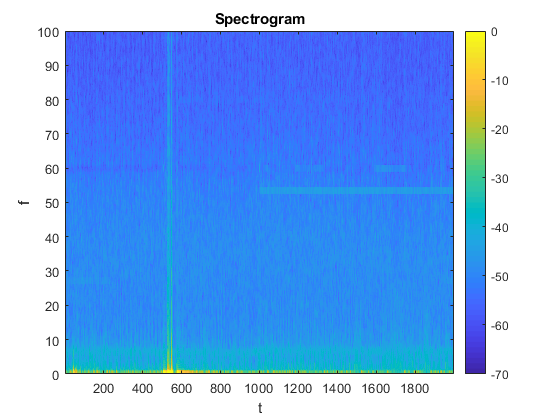

%%%Test: plot specgram to look for 52 hz signal seen in power/frequency spectrum

plot_spectrogram(KO_unhab_cat, [5 .5], params)

segave = 1

S = 1639×1 single column vector
    0.1360
    0.1395
    0.1363
    0.1342
    0.1330
    0.1245
    0.1219
    0.0905
    0.0563
    0.0165


f =          0    0.0610    0.1221    0.1831    0.2441    0.3052    0.3662    0.4272    0.4883    0.5493    0.6104    0.6714    0.7324    0.7935    0.8545    0.9155    0.9766    1.0376    1.0986    1.1597    1.2207    1.2817    1.3428    1.4038    1.4648    1.5259    1.5869    1.6479    1.7090    1.7700    1.8311    1.8921    1.9531    2.0142    2.0752    2.1362    2.1973    2.2583    2.3193    2.3804    2.4414    2.5024    2.5635    2.6245    2.6855    2.7466    2.8076    2.8687    2.9297    2.9907


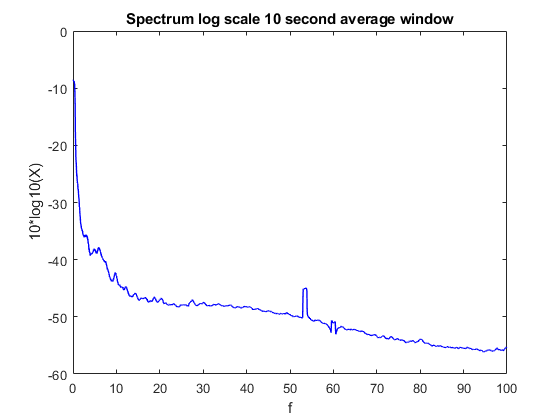



plot_spectrum_seg(KO_unhab_cat, 10, params)

## Scrap


%{
data = LFP(:,2);



 


% Frequency spectrum
[S,f] = mtspectrumc(data,params);


figure; plot_vector(S,f); title('Raw data spectrum log scale');
figure; plot_vector(S,f,'n'); title('Raw data spectrum linear scale')%linear scale

%spectrogeam no average
movingwin = [5 .5]

[S1, t1, f1] = mtspecgramc(data,movingwin,params)
figure; plot_matrix(S1,t1,f1); caxis([-100 0])



win = 10 % length in seconds to average over

segave = 1 
[S,f]=mtspectrumsegc(data,win,params,segave)
figure; plot_vector(S,f); title('Spectrum log scale 10 second average window'); 

%}




%{
% removing 60 Hz
alpha = 0.999; 
omega = 2*pi*60/params.Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];
datano60 = filter(num,den,data);
[S,f] = mtspectrumc(datano60,params);
figure; plot_vector(S,f); title('Spectrum after 60 Hz notch');
%}


# Functions to be used 

## Interatively Run LFP Analysis

function result = run_lfp_analysis(cell_array_standardized)
for ii = 1:length(cell_array_standardized)
    LFP = cell_array_standardized{ii}
    lfp_analysis_CH
end
end


## Standardize Length of Arrays



function result = standardize_length(cell_array, len)
% This function takes a cell array (cell_array) containing a set of arrays
% and makes them all the same length (len) from 1 to len
for ii = 1:length(cell_array)
    cell_array{ii} = cell_array{ii}(1:len,:)
end
result = cell_array
end


## Remove 60Hz Noise

function result = remove60(cell_array, Fs)
% This function removes 60 Hz noise from signal

% Set parameters for filter

%%%%global params.Fs

alpha = 0.998; 
omega = 2*pi*60/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

for ii = 1:length(cell_array)
    cell_array{ii}(:,2) = (filter(num,den,cell_array{ii}(:,2)))
end
result = cell_array
end

## Vertically Concatenate Cell Array

function result = vertcat_cell_array(cell_array)
x = cell_array{1}
for ii = 2: length(cell_array)
    x = vertcat(x,cell_array{ii}) 
end
result = x
end

## Calulate and Plot Spectrum over Average Window

function result = plot_spectrum_seg(arrayx, window, params)

% window is length in seconds to average over
segave = 1 
[S,f]=mtspectrumsegc(arrayx(:,2),window,params,segave)
figure; plot_vector(S,f); title('Spectrum log scale 10 second average window'); ylim([-60 -10])

end

## Calculate and Plot Spectrogram

function result = plot_spectrogram (arrayx, movingwin, params)

[S2, t2, f2] = mtspecgramc(arrayx(:,2), movingwin,params)
figure; plot_matrix(S2,t2,f2); colorbar; colormap jet; caxis ([-70 0])

end